# Effect of broadening parameter $b_\mathrm{p}$ to interference function

This script confirms the effect of the broadening parameter $b_\mathrm{p}$ on the observation process $\mathbf{P}$.

Reference:

-  Ruiki Kobayashi, Genki Fujii, Yuta Yoshida, Takeru Ota, Fumiaki Nin, Hiroshi Hibino, Samuel Choi, Shunsuke Ono, and Shogo Muramatsu, "**Sparsity-Aware OCT Volumetric Data Restoration Using an Optical Synthesis Model**,"  submitted to* IEEE Trans. on Computational Imaging*, 2022

-  Genki Fujii, Yuta Yoshida, Shogo Muramatsu, Shunsuke Ono, Samuel Choi, Takeru Ota, Fumiaki Nin, and Hiroshi Hibino, “**OCT Volumetric Data Restoration with Latent Distribution of Refractive Index**,” in *Proceedings of International Conference on Image Processing, (ICIP)*, pp. 764–768, Sept. 2019.

Copyright © 2022 Ruiki KOBAYASHI and Shogo MURAMATSU

## Measurement process in Z-direction

   
$$p_\mathrm{z}[m_\mathrm{z}]=\exp \left(-\frac{m_{\mathrm{z}}^{2}}{2 \sigma_{\mathrm{z}}^{2}}\right) \cos \left(\omega_{\mathrm{p}} m_{\mathrm{z}}\right) \mathrm{sinc}\left(b_\mathrm{p} m_{\mathrm{z}}\right), m_\mathrm{z}\in\mathbb{Z}$$


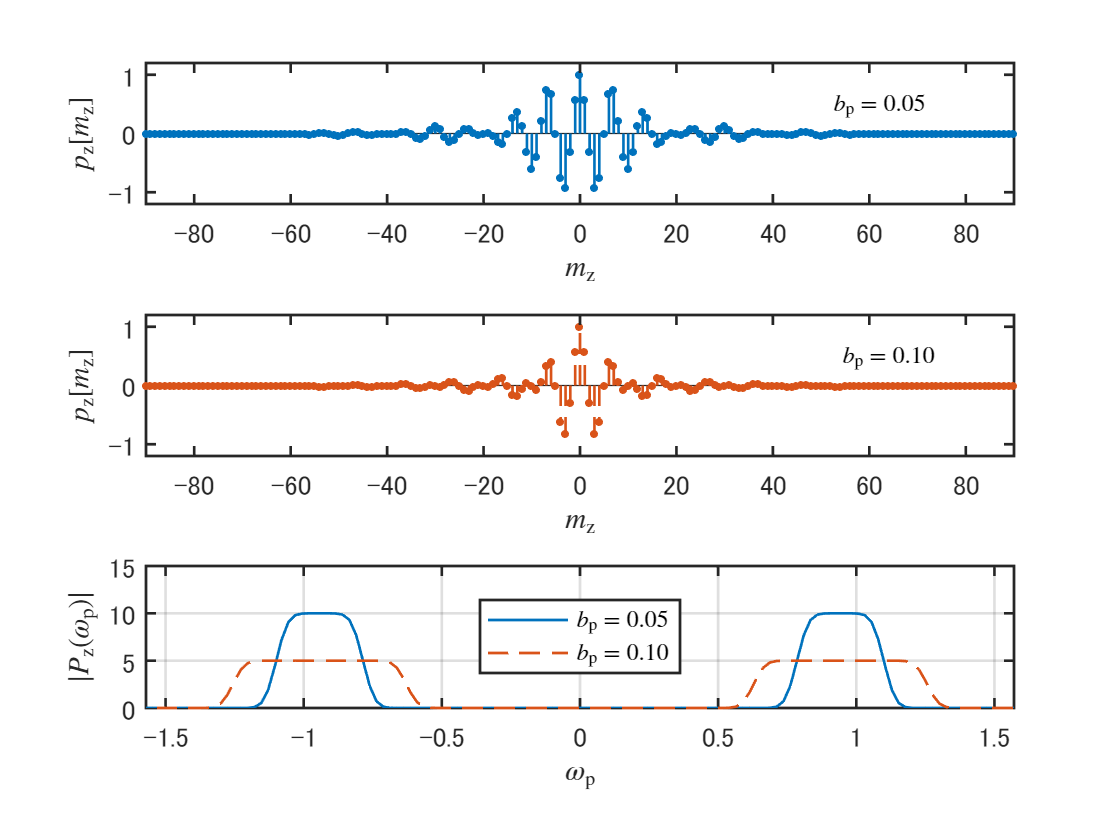

nSamples = 256; % Number of samples

% Parameters
omega_p = 0.3*pi; % Frequency of fluctuation
sigma_z = 30; % Standard deviation of Gaussian function
b_p = 0.05; % Broadening parameter

% Impluse response of measurement process
pz = @(m,b) exp(-m.^2/(2*sigma_z.^2)).*cos(omega_p*m).*sinc(b*m);
% Impulse response of P
hlen = round(3*sigma_z); 
zsmpl = -hlen:hlen;
irp1 = pz(zsmpl,b_p); % impluse response of p
irp2 = pz(zsmpl,2*b_p); % impluse response of p

hfig = figure;
% Coherence funciton
subplot(3,1,1)
stem(-hlen:hlen,irp1,'filled','MarkerSize',2)
axis([-hlen hlen -1.2 1.2])
xlabel('$m_\mathrm{z}$','Interpreter','latex')
ylabel('$p_\mathrm{z}[m_\mathrm{z}]$','Interpreter','latex')
text(52,0.5,['$b_\mathrm{p} = $' num2str(b_p,'%4.2f')],'Interpreter','latex')

% Coherence function
subplot(3,1,2)
stem(-hlen:hlen,irp2,'filled','MarkerSize',2,'LineStyle','--','Color',[0.8500 0.3250 0.0980])
axis([-hlen hlen -1.2 1.2])
xlabel('$m_\mathrm{z}$','Interpreter','latex')
ylabel('$p_\mathrm{z}[m_\mathrm{z}]$','Interpreter','latex')
text(54,0.5,['$b_\mathrm{p} = $' num2str(2*b_p,'%4.2f')],'Interpreter','latex')

%
subplot(3,1,3)
wz = linspace(-pi,pi-(2*pi)/nSamples,nSamples);
%
arp1 = fftshift(abs(fft(irp1,nSamples)));
plot(wz,arp1)
hold on
%
arp2 = fftshift(abs(fft(irp2,nSamples)));
text(54,0.5,['$b_\mathrm{p} = $' num2str(2*b_p,'%4.2f')],'Interpreter','latex')
plot(wz,arp2,'--')
%
xlabel('$\omega_\mathrm{p}$','Interpreter','latex')
ylabel('$|P_\mathrm{z}(\omega_\mathrm{p})|$','Interpreter','latex')
axis([-pi/2 pi/2 0 sigma_z/2])
grid on
hold off

viewhandle_(hfig)
legend({['$b_\mathrm{p} = $' num2str(b_p,'%4.2f')],['$b_\mathrm{p} = $' num2str(2*b_p,'%4.2f')]},'Location','best','Interpreter','latex')

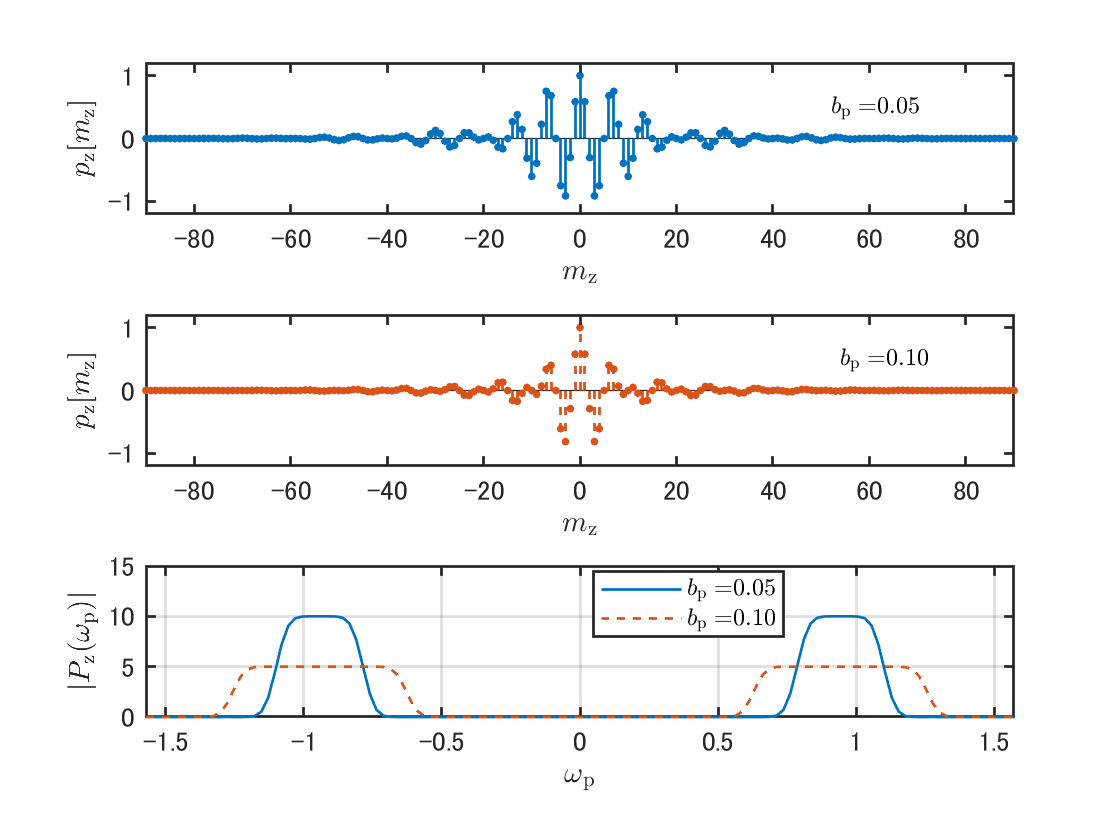

%print(hfig,'./results/figpz','-dpng','-r',300)
exportgraphics(hfig,'./results/fig3rev.png','Resolution',300) 

close(hfig)
%{
subplot(3,1,1)
ax = gca;
exportgraphics(ax,'./results/figpza.png','Resolution',300) 
subplot(3,1,2)
ax = gca;
exportgraphics(ax,'./results/figpzb.png','Resolution',300) 
subplot(3,1,3)
ax = gca;
exportgraphics(ax,'./results/figpzc.png','Resolution',300) 
%}

## Relation between refractive index and reflection 

    
$$R=\frac{|\mathfrak{n}_1-\mathfrak{n}_2|(\mathfrak{n}_1-\mathfrak{n}_2)}{(\mathfrak{n}_1+\mathfrak{n}_2)^2},\ \mathfrak{n}_1,\mathfrak{n}_2\in[0,\infty)$$


hfig = figure;
%
subplot(3,1,1)
%
colormap(pink)
for idx = 1:3
    [X,Y,Z] = ellipsoid(-48*(idx-2),0,0,24,32,32);
    s = surf(X,Y,Z,'EdgeColor','none','FaceColor','interp');
    direction = [0 0 1];
    rotate(s,direction,-30,[-48*(idx-2) 0 0])
    hold on
end
% Arrow 
line([-2*hlen 2*hlen],[0 0],[0 0],'Color',[0.4660 0.6740 0.1880],'LineWidth',1)
line([2*hlen-4 2*hlen],[4 0],'Color',[0.4660 0.6740 0.1880],'LineWidth',1)
line([2*hlen-4 2*hlen],[-4 0],'Color',[0.4660 0.6740 0.1880],'LineWidth',1)
view(0,90)
axis off
daspect([1 1 1])

ans =      2     2     2


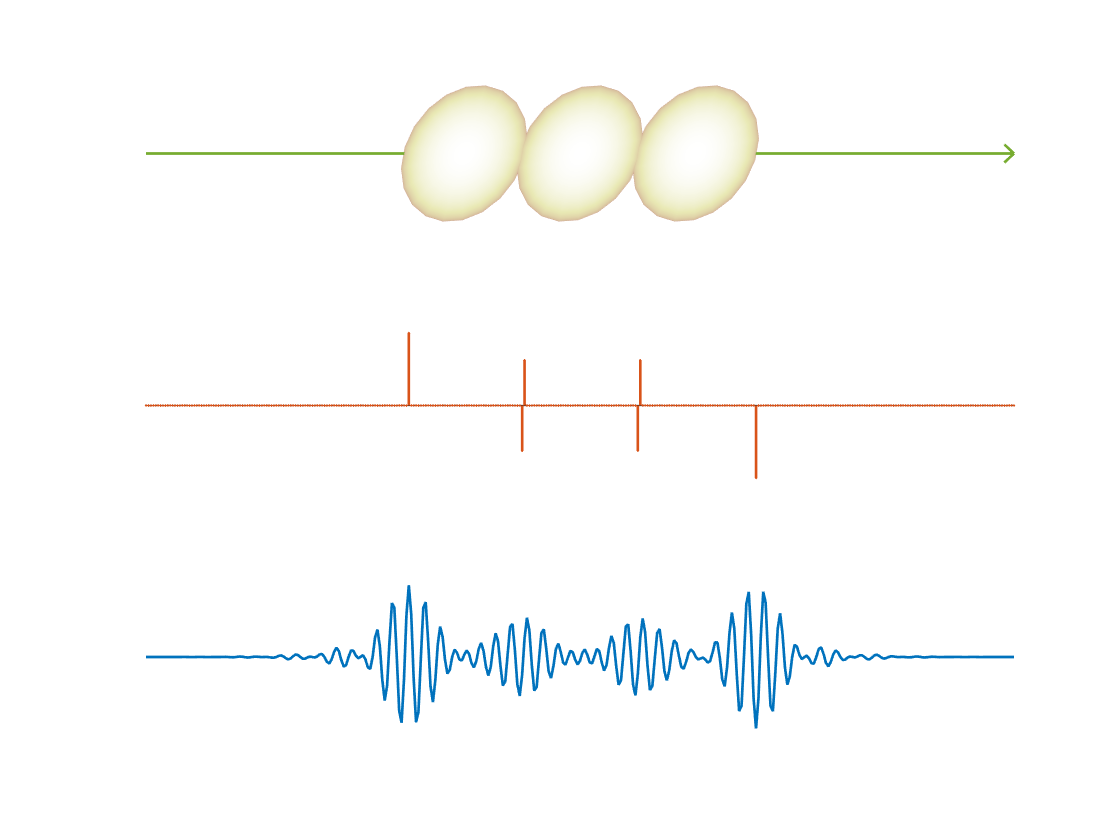

ha = gca;
ha.XLim = [-2*hlen 2*hlen];
hold off
% Reflection
subplot(3,1,2)
rdist = zeros(4*hlen+1,1);
rdist(110) = 0.8;
rdist(157) = -0.5;
rdist(158) = 0.5;
rdist(205) = -0.5;
rdist(206) = 0.5;
rdist(254) = -0.8;
zeta = linspace(-2*hlen,2*hlen,4*hlen+1);
stem(zeta,rdist,'LineWidth',1,'MarkerSize',0.1,'Color',[0.8500 0.3250 0.0980])
axis([-2*hlen 2*hlen -1 1])
axis off
%
irp = pz(zeta,0.05);
subplot(3,1,3)
v = circshift(cconv(rdist,irp,length(rdist)),-floor(length(irp)/2));
plot(zeta,v,'LineWidth',1)
axis([-2*hlen 2*hlen -1 1])
axis off
print(hfig,'./results/rid2rd','-dpng')

## Function for handling figures

function viewhandle_(hfig)
axes = hfig.Children;
nAxes = length(axes);
for iAxis = 1:nAxes
    haxis_ = axes(iAxis);
    haxis_.LineWidth = 1;
    haxis_.FontSize = 10;
    %haxis_.XGrid = 'on';
    %haxis_.YGrid = 'on';
    hcontents_ = haxis_.Children;
    nContents = length(hcontents_);
    for iContent = 1:nContents
        hcontent_ = hcontents_(iContent);
        hcontent_.LineWidth = 1;
    end
end
end